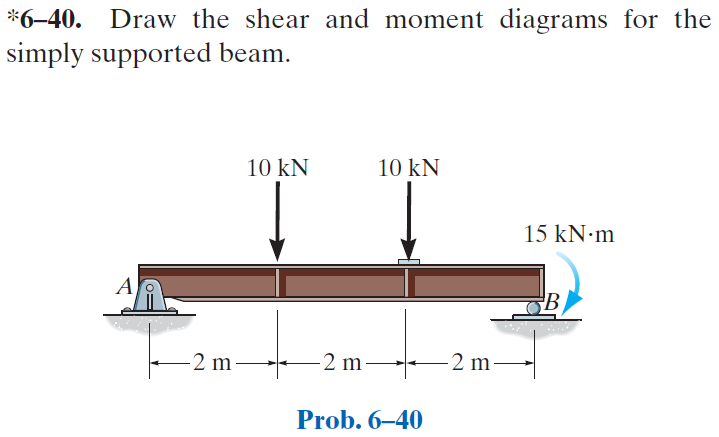

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-40P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-40P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam; 
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('concentrated', 'force', -10*u.kN, 2*u.m);
b = b.add('concentrated', 'force', -10*u.kN, 4*u.m);
b = b.add('concentrated', 'moment', -15*u.kN*u.m, 6*u.m);
b.L = 6*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(20\,m^{2}-x^{2}\right)}{4\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ -\frac{5\,\left(x^{3}-24\,x^{2}\,m+108\,x\,m^{2}-32\,m^{3}\right)}{12\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{5\,\left(x-6\,m\right)\,\left(5\,x^{2}-42\,x\,m+48\,m^{2}\right)}{12\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(20\,m^{2}-3\,x^{2}\right)}{4\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ -\frac{5\,\left(x^{2}-16\,x\,m+36\,m^{2}\right)}{4\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{5\,\left(5\,x^{2}-48\,x\,m+100\,m^{2}\right)}{4\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{15\,x}{2}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ -\frac{5\,\left(x-8\,m\right)}{2}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{5\,\left(5\,x-24\,m\right)}{2}\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{15}{2}\,\mathrm{kN} & \text{ if }x\leq 2\,m\\ -\frac{5}{2}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,4\,m\right]\\ -\frac{25}{2}\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 7.5\,\mathrm{kN}\\ \mathrm{Rb} & 12.5\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

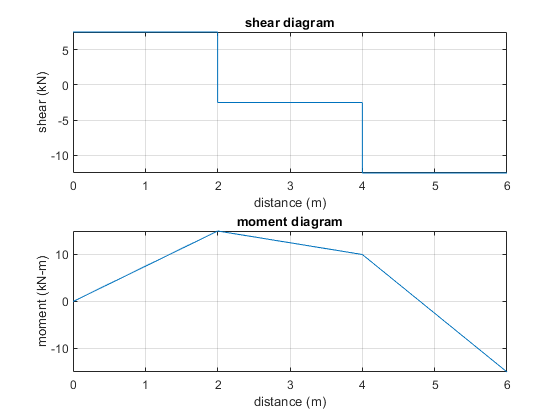

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;